# Communication system design insights from capacit curves

## Introduction

Consider a usual scenario where we have a mobile receiver (a cellphone for ex). From the perspective of a physical layer engineer, the major constraints are the SNR and the available bandwidth. Given the constraints, the goal is to maximize the bit rate or in other words, the spectral efficiency, and the engineer has the option to chose the right modulation and channel coding scheme. 

The task of "maximizing" the spectral eficiency immediately raises the question: "What is the optimal value"? This optimality is addressed using capacity theorems. In case of AWGN channels for example, these theorems express the relationship between the optimal spectral efficiency, the noise (usally power spectral density $N_0$, and the energy available per information bit ($E_b$). Note that the ratio $E_b/N_0$ is not the same as SNR ($E_s/N_0$) where $E_s$ is the average energy per received symbol. However, the constraint dictated by the hardware is in the form of $E_s/N_0$. This document discusses the interplay between all these terms and how one can use the capacity curves to gain insight into the design of a communication system. 

## Spectral efficiency for capacity achieving schemes

The spectral efficiency of an AWGN channel is given as 


$$\eta_c = log_2\left( 1 + \eta_c \frac{E_b}{N_0} \right)$$


or 


$$\frac{E_b}{N_0} = \frac{2^{\eta_c} -1}{\eta_c}$$


where $E_b$ is the energy per bit and $N_0$ is the power spectral density.  The figure below visualizes this curve. 

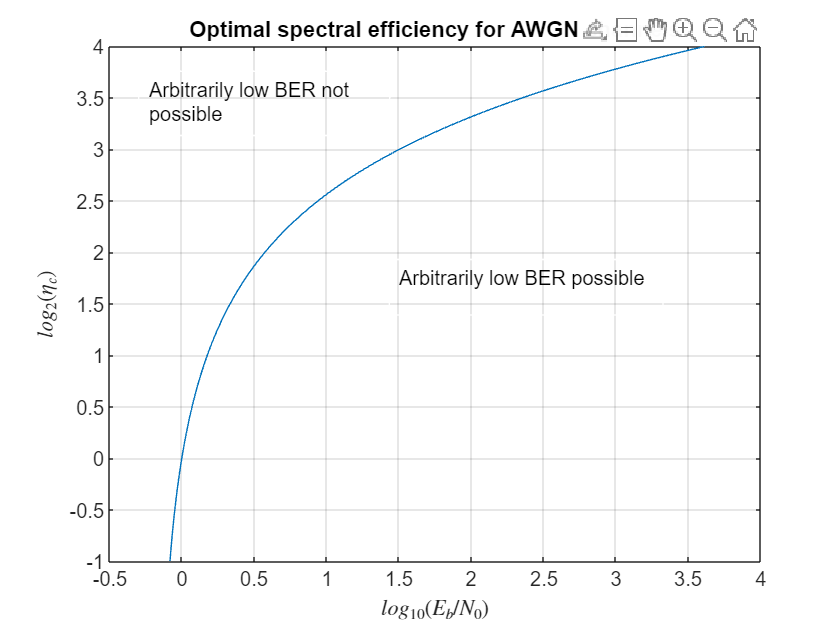

h1 = plotOptimalCurve();
a1 = annotation(h1,'textbox',[0.165 0.785 0.299 0.102],...
    'String',{'Arbitrarily low BER not','possible'},'EdgeColor',[1 1 1]);
a2 = annotation(h1,'textbox',[0.4635 0.5 0.325785714285714 0.08809523809524],...
    'String',{'Arbitrarily low BER possible'},'EdgeColor',[1 1 1], 'Tag', 'possilbe');

As per Shannon's theorem, if the operating point is to the right of the curve, it is possible to chose to modulation and coding scheme to achieve any arbitrarily low BER. Conversely, if the operating point is to the left of the curve, the BER will be positively lower bounded. 

### Practical implications

In practice, we never have a zero (or even negligible) BERs. Many standards specify an acceptable BER. For example, the acceptable BER for the Ethernet standard is $10^{-10}$. However, the above diagram can still provide a valuable insight: For a given SNR, as the operating point moves away from the curve to the right, BER decreases. 

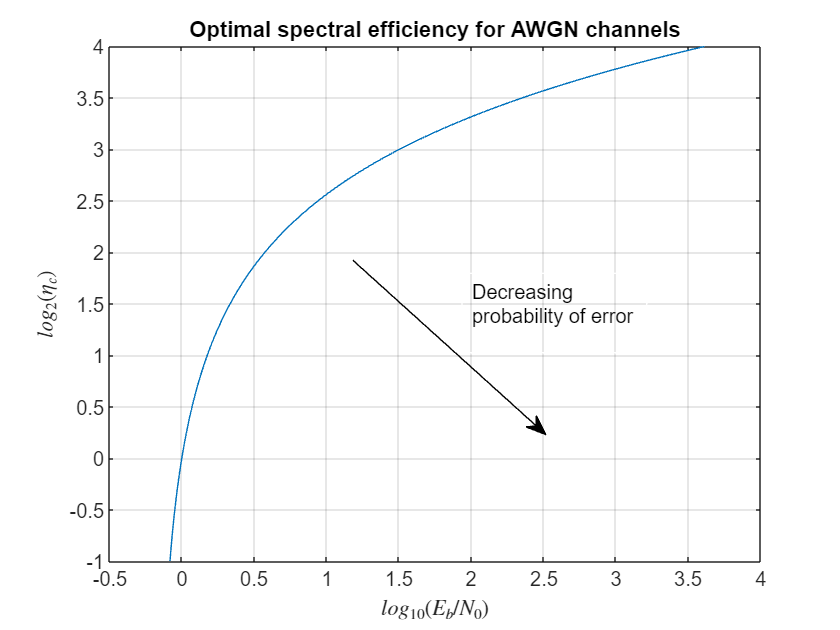

h1 = plotOptimalCurve(); 
a3 = annotation(h1,'arrow',[0.42 0.65], [0.587 0.31]);
a4 = annotation(h1,'textbox',[0.55 0.44 0.22 0.126],...
    'String',{'Decreasing','probability of error'},...
    'FitBoxToText','off',...
    'EdgeColor',[1 1 1]);

## Spectral efficiency of a given modulation scheme

To reiterate, given a certain $E_s/N_0$ value, the task is to pick the right modulation and coding schemes to maximize the spectral efficiency while maintaining a tolerable BER. The relationship between $E_s/N_0$ and $E_b/N_0$ is given as 


$$\frac{E_b}{N_0} = (1/r)\frac{E_s}{N_0},$$


where $r$ is the coderate. Using $M$-order QAM modulation, using raised cosine signaling with roll-off factor $\alpha$, and signaling rate (baud rate/symbol rate) equat to $R$. The spectral efficiency (bits/sec/hz) is given as 


$$\eta = \frac{r * log_2(M)*R}{(1+\alpha)R} = \frac{r * log_2(M)}{(1+\alpha)}$$


We can make a few observations (assuming the signal shape ($\alpha$) if fixed) : 

- If the signal shape is fixed, the spectral efficiency only depends on the modulation order and the code rate. 

- Decreasing the code rate $r$ decreases the spectral efficiency $\eta$ and increases the energy per bit $E_b$. This can be interpreted as saying adding coding moves the operating point away from the boundary line and deeper into the feasible region.

- Given the discrete nature of $M$(integer powers of 2), not all points in the feasible region are achievable for a given $E_s/N_0$. Here, we are assuming that we can achieve any real value of $r<1$ (which is technically possible). Therefore, for each value of $M$we get a curve (locus) for changing values of $r$.  

Let us plot and see how these curves look like. We will set $E_s/N_0$=10. Then we have a locus of operating points for value of $M=2,4,8,16,...$.  (Assuming $\alpha = 0$)

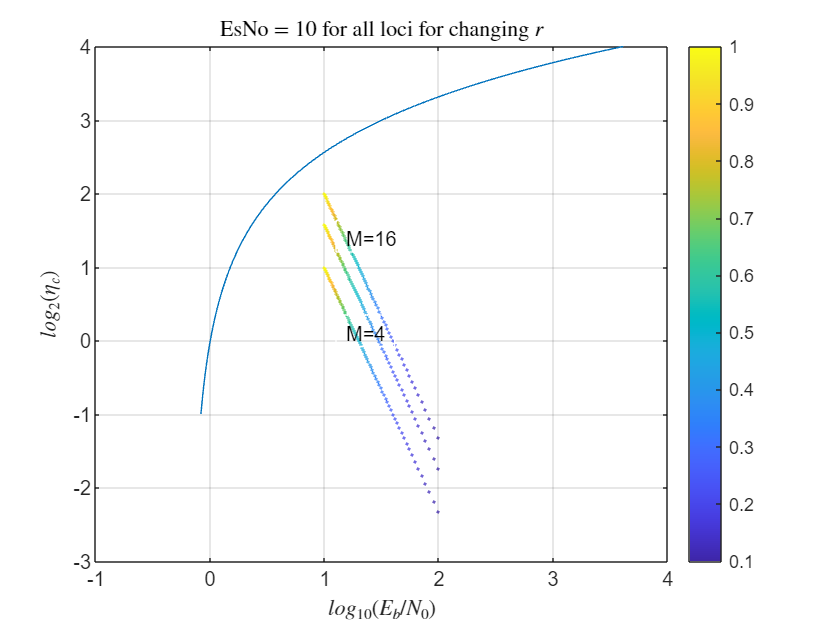

EsNo = 10; 
Ms = 2.^(2:4); 
rs = 0.1:0.01:1; 
eta = 2.^(-1:0.01:4); 
EbNo = ((2.^eta)-1)./eta; 
h1 = figure(); 
plot(log10(EbNo), log2(eta)); 
hold on; 
grid on
xlabel("$log_{10}(E_b/N_0)$", 'Interpreter','latex');
ylabel("$log_2(\eta_c)$", 'Interpreter','latex'); 

for M = Ms
    EbNo = (1./rs)*EsNo; 
    eta = rs*log2(M); 
    scatter(log10(EbNo), log2(eta),1,rs); 
end
colorbar
annotation(h1, 'textbox', [0.4,0.45,0.07,0.05], 'String',{'M=4'}, 'EdgeColor',[1 1 1]); 
annotation(h1, 'textbox', [0.4,0.6,0.07,0.05], 'String',{'M=16'}, 'EdgeColor',[1 1 1]);
title('EsNo = 10 for all loci for changing $r$', 'Interpreter','latex');
hold off; 

As seen in the above plot, as the value of $r$ decreases, the operating point moves away from the optimal curve for a given SNR. This is expected because decreasing $r$ means increasing the number of parity bits which should result in decreasing probability of error. However, this comes at the cost of reduced spectral efficiency. This interplay can be visualized neatly in the above diagram. 

### Modulation order and coderate

 For a given spectral efficiency and SNR, there could be several $M$-loci which can achieve the desired $\eta$.  For example, if we desirec a spectral efficiency $\eta = 2$bits/sec/hz, we will have several $(r,M)$ pairs which can achieve this for a given $E_b/N_0 = 10$ as shown in the figure below. 

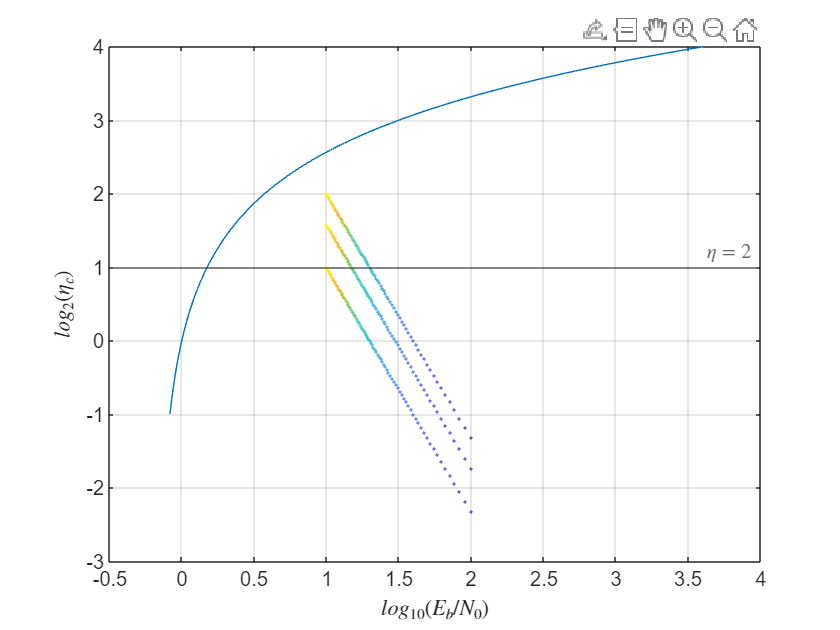

h1 = plotOptimalCurve(); 
hold on; 
yline(1, '-', '$\eta = 2$', 'Interpreter','latex'); 
for M = Ms
    EbNo = (1./rs)*EsNo; 
    eta = rs*log2(M); 
    scatter(log10(EbNo), log2(eta),1,rs); 
end
title('');
hold off; 

My hypothesis is that higher order modulation schemes will produce higher BER for the same spectral efficiency. It will be interesting to compare the BERs for different coding schemes for the same operating point.

%determine the (k,M) pairs 
EsNo = 10; 
Ms = 2.^(2:4);
eta = 2; 
rs = eta./log2(Ms);
%generate binary data 

%perform channel coding 
n = 15

n = 15

r = rs(3); 
k = round(r*n);
rActual = k/n

rActual = 0.5333

t = bchnumerr(n)

t =     15    11     1
    15     7     2
    15     5     3


%convert chunks (according to M) to complex numbers using Gray coding

%add noise 

%demodulate to recover codebits 

%channel decode 

%compute BER 


## Helper functions

function h1 = plotOptimalCurve()
    eta = 2.^(-1:0.01:4); 
    EbNo = ((2.^eta)-1)./eta; 
    h1 = figure(); 
    plot(log10(EbNo), log2(eta)); 
    grid on
    xlabel("$log_{10}(E_b/N_0)$", 'Interpreter','latex');
    ylabel("$log_2(\eta_c)$", 'Interpreter','latex'); 
    title('Optimal spectral efficiency for AWGN channels'); 
end